#### AERO50003

#### Introduction to Numerical Methods for ODEs and PDEs

### **Tutorial Sheet 1**

## Finite Differences

Masoud Seifikar

Autumn Term 2023

Department of Aeronautics, Imperial College London 

#### Exercise 1 (The first derivative of a sinusoidal function)

Consider the function

f(x) = sin(x), 

and the interval x ∈ [0, 15]. We wish to compute the derivative of f(x) numerically. To do so, we create a grid of uniformly spaced points (for the variable x) from x = 0 to x = 15. Let this uniform spacing be some constant h > 0. We can label each point on the grid as x1, x2, . . . , xN (where, differently from the lecture notes, we start with the index 1 instead of the index 0 to be consistent with the syntax of Matlab). 

1. Determine the derivative of f(x) with respect to x analytically. 

(a) Plot the derivative of the function for x in the interval of interest. 

(b) Pick h = 0.5 (we will vary the grid sizing later) and plot (on the same figure), using asterisks, the (exact) derivative of f(x) at each grid point.

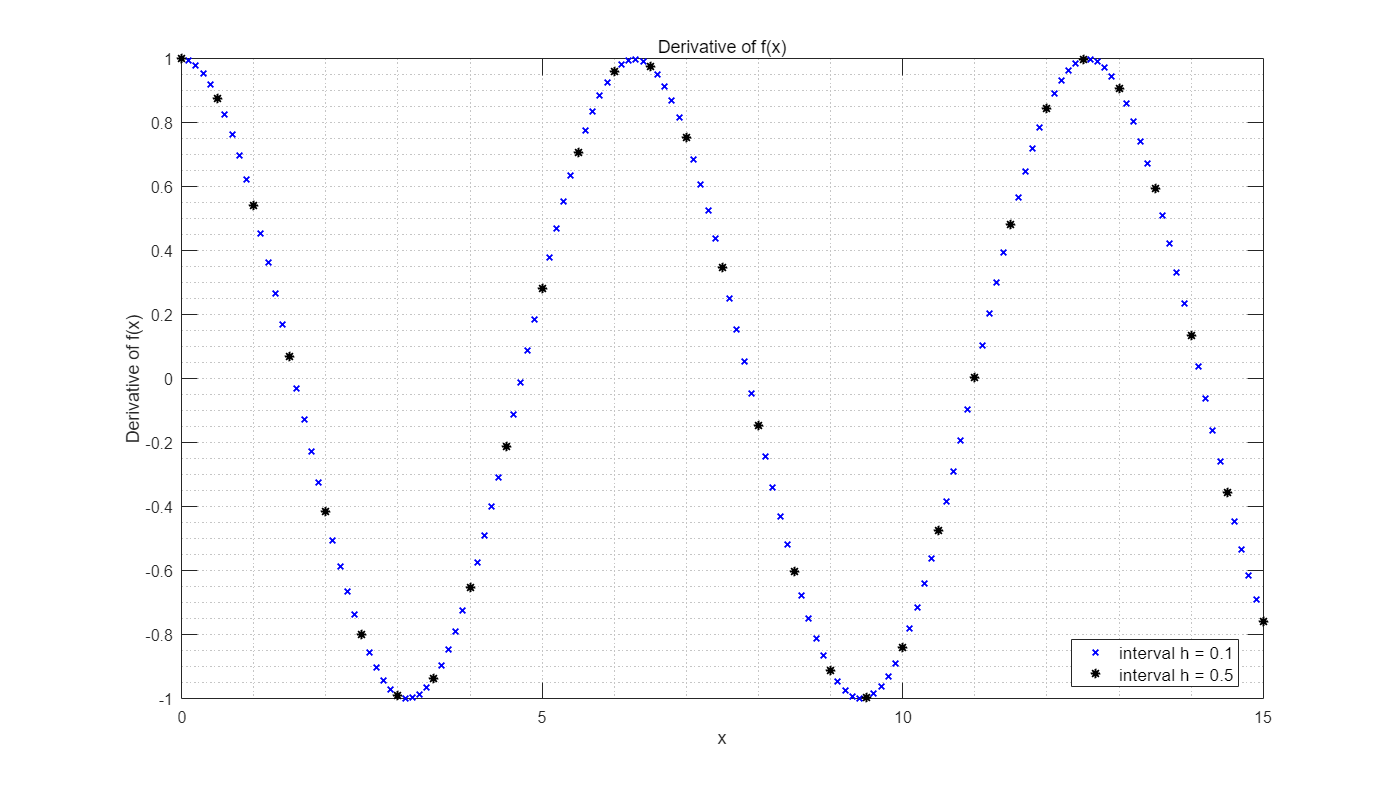

% Housekeeping
clear
clc
close all

% Define the interval
ha = 0.1;
hb = 0.5;

% Create grids of uniformly spaced points
Xa = 0 : ha : 15;
Xb = 0 : hb : 15;

% Determine the derivative of f(x)
syms x;       % create a symbolic expression
f = sin(x);   % define the function
fd = diff(f); % differentiates f

fda = double(subs(fd, x, Xa)); % for ha
fdb = double(subs(fd, x, Xb)); % for hb

% Plot the derivative of the function
plot(Xa, fda, 'xb', LineWidth = 1.5, MarkerSize = 6); % plot derivative of f(x) in the interval of interest for ha
hold on
plot(Xb, fdb, '*k', LineWidth = 1.5, MarkerSize = 7); % plot derivative of f(x) in the interval of interest for hb
hold off

title('Derivative of f(x)', FontSize = 15);
legend(['interval h = ', num2str(ha)], [ 'interval h = ', num2str(hb) ], 'Location', 'Best', FontSize = 13)

xlabel('x'); 
ylabel('Derivative of f(x)');
set(gca, 'FontSize', 12)                            % set the fontsize of the axis

grid minor;                                         % set the grid of the graph
set(gcf, 'Position', [0 0 1920 1080]);              % show plot with larger size

2. We now wish to compute the derivative numerically using first order forward differencing with h = 0.5. 

(a) Use first order forward differencing to approximate the derivative of the function at the gridpoints x1, . . . , xN−1. 

(b) Plot, using an asterisk, the numerical approximation of the derivative computed in part (a).

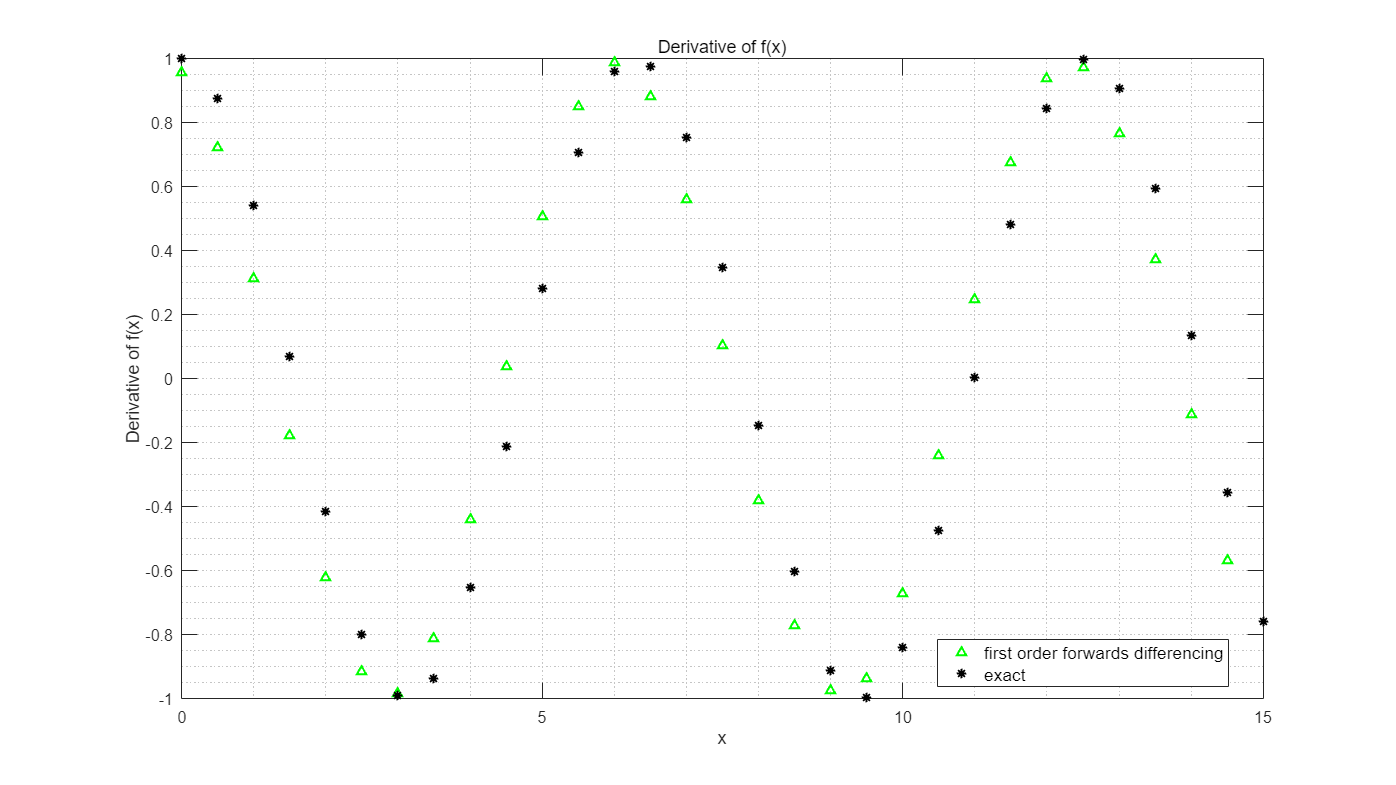

% Use first order forwards differencing to approximate the derivative of the function
fd2 = zeros(1, length(Xb) - 1); % create empty matrix to store data
fx2 = sin(Xb);                  % define the value of f(x) at each gird point

for i = 1 : length (Xb) - 1
    fd2(i) = (fx2(i + 1) - fx2(i)) / hb; % approximate the derivative of the function
end

% Plot the approximated derivative of the function and compare with the exact one
plot(Xb(1 : length(Xb) - 1), fd2, '^g', LineWidth = 1.5, MarkerSize = 6); % plot first order forwards differencing
hold on
plot(Xb, fdb, '*k', LineWidth = 1.5, MarkerSize = 7);                     % plot exact derivative of f(x)
hold off

title('Derivative of f(x)', FontSize = 15);
legend('first order forwards differencing', 'exact', 'Location', 'Best', FontSize = 13)

xlabel('x'); 
ylabel('Derivative of f(x)');
set(gca, 'FontSize', 12)                                                  % set the fontsize of the axis

grid minor;                                                               % set the grid of the graph

3. We now wish to compute the derivative numerically using first order bakcwards differencing with h = 0.5. 

(a) Use first order backwards differencing to approximate the derivative of the function at the gridpoints x2, . . . , xN . 

(b) Plot, using an asterisk, the numerical approximation of the derivative computed in part (a). 

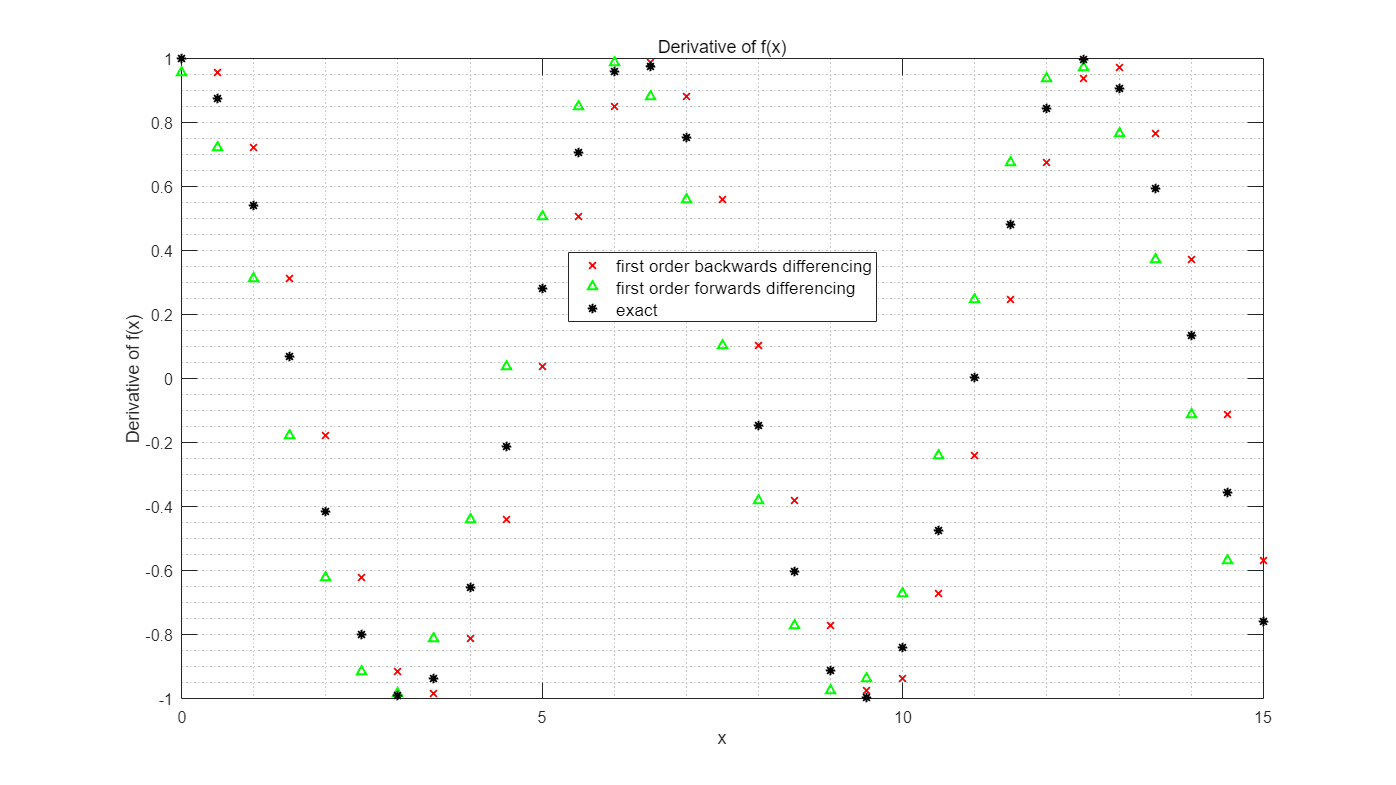

% Use first order backwards differencing to approximate the derivative of the function
fd3 = zeros(1, length(Xb) - 1); % create empty matrix to store data
fx3 = sin(Xb);                  % define the value of f(x) at each gird point

for i = 2 : length (Xb)
    fd3(i - 1) = (fx3(i) - fx3(i - 1)) / hb; % approximate the derivative of the function
end

% Plot the approximated derivative of the function and compare with the previous two
plot(Xb(2 : length(Xb)), fd3, 'xr', LineWidth = 1.5, MarkerSize = 7);     % plot first order backwards differencing
hold on
plot(Xb(1 : length(Xb) - 1), fd2, '^g', LineWidth = 1.5, MarkerSize = 6); % plot first order forwards differencing
hold on
plot(Xb, fdb, '*k', LineWidth = 1.5, MarkerSize = 7);                     % plot exact derivative of f(x)
hold off

title('Derivative of f(x)', FontSize = 15);
legend('first order backwards differencing', 'first order forwards differencing', 'exact', 'Location', 'Best', FontSize = 13)

xlabel('x'); 
ylabel('Derivative of f(x)');
set(gca, 'FontSize', 12)                                                  % set the fontsize of the axis

grid minor;                                                               % set the grid of the graph

4. We now wish to compute the derivative numerically using second order central differencing with h = 0.5. 

(a) Use first order forwards differencing to approximate the derivative of the function at the gridpoint x1. 

(b) Use second order central differencing to approximate the derivative of the function at the gridpoints x2, . . . , xN−1. 

(c) Use first order backwards differencing to approximate the derivative of the function at the gridpoint xN. 

(d) Plot, using an asterisk, the numerical approximation of the derivative computed in parts (a)-(c).

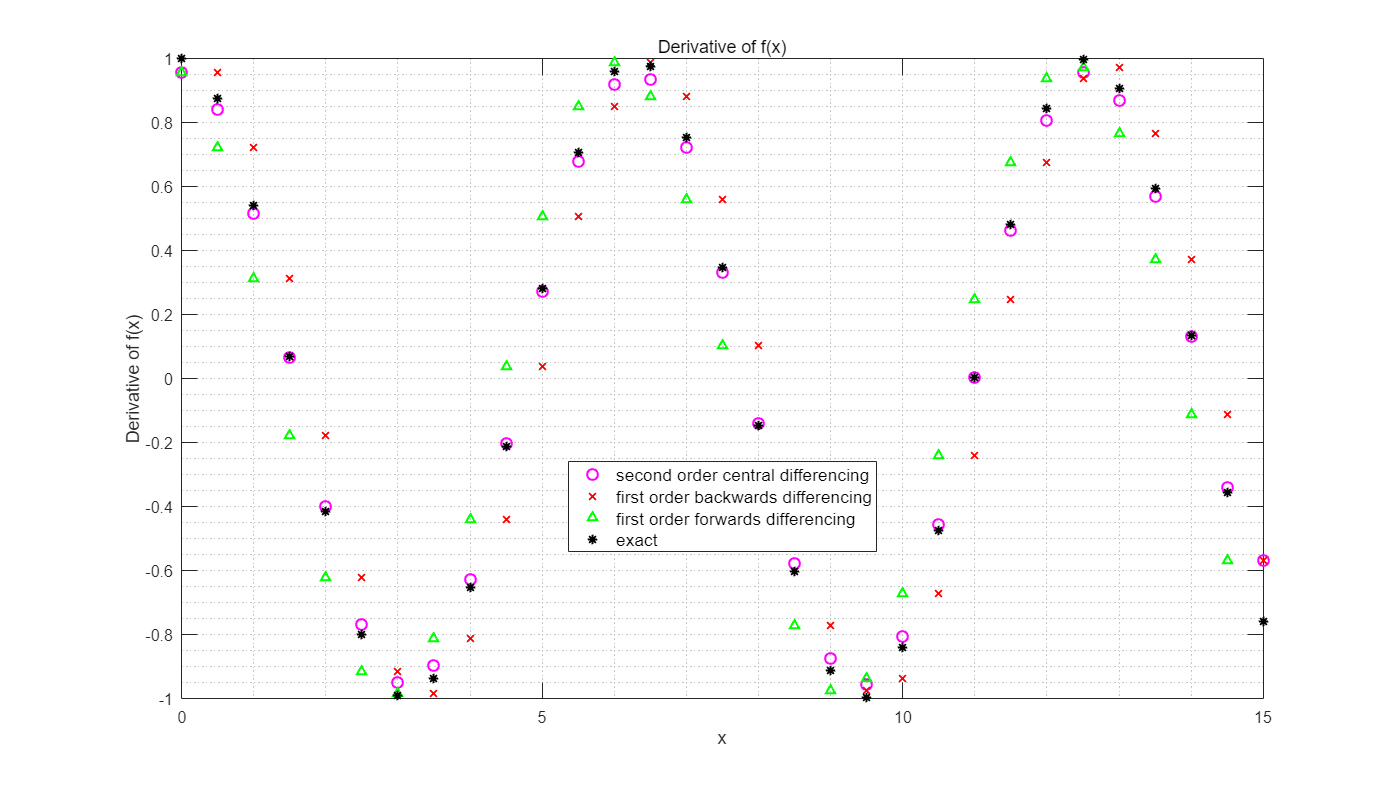

% Use second order central differencing to approximate the derivative of the function
fd4 = zeros(1, length(Xb)); % create empty matrix to store data
fx4 = sin(Xb);              % define the value of f(x) at each gird point

fd4(1) = fd2(1); % use first order forwards differencing at the gridpoint x1

for i = 2 : length (Xb) - 1
    fd4(i) = (fx4(i + 1) - fx4(i - 1)) / (2 * hb); % use second order central differencing at the gridpoints x2, . . . , xN−1
end

fd4(length(Xb)) = fd3(length(Xb) - 1); % use first order backwards differencing at the gridpoint xN

% Plot the approximated derivative of the function and compare with the previous three
plot(Xb(1 : length(Xb)), fd4, 'om', LineWidth = 1.5, MarkerSize = 8);     % plot second order central differencing
hold on
plot(Xb(2 : length(Xb)), fd3, 'xr', LineWidth = 1.5, MarkerSize = 7);     % plot first order backwards differencing
hold on
plot(Xb(1 : length(Xb) - 1), fd2, '^g', LineWidth = 1.5, MarkerSize = 6); % plot first order forwards differencing
hold on
plot(Xb, fdb, '*k', LineWidth = 1.5, MarkerSize = 7);                     % plot exact derivative of f(x)
hold off

title('Derivative of f(x)', FontSize = 15);
legend('second order central differencing', 'first order backwards differencing', ...
    'first order forwards differencing', 'exact', 'Location', 'Best', FontSize = 13)

xlabel('x'); 
ylabel('Derivative of f(x)');
set(gca, 'FontSize', 12)                                                  % set the fontsize of the axis

grid minor;                                                               % set the grid of the graph

5. Repeat parts 1-3 with different grid spacing h and compare the “numerical approximations” with the derivative calculated analytically for the different values of h. In particular, let the gridspacing vary from 0.1 to 1 (feel free to experiment with values outside of this range too!). What do you observe? (It may be beneficial to plot the derivative and the various numerical approximations on the same figure.) 

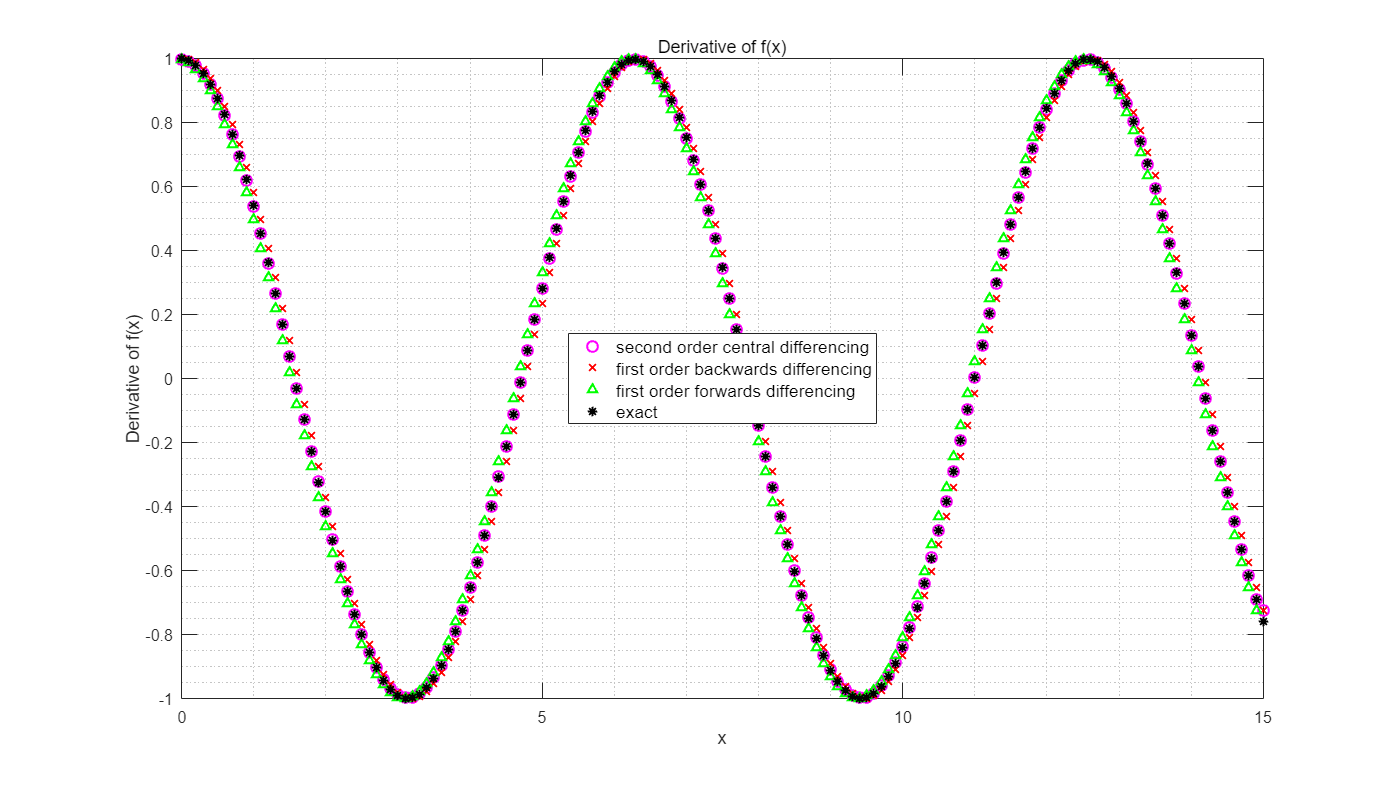

% Repeat parts 1-3 with grid spacing h=0.1

% Housekeeping
clear
clc

% Define the interval
hb = 0.1;

% Create grids of uniformly spaced points
Xb = 0 : hb : 15;

% Determine the derivative of f(x)
syms x;       % create a symbolic expression
f = sin(x);   % define the function
fd = diff(f); % differentiates f

fdb = double(subs(fd, x, Xb));

% Use first order forwards differencing to approximate the derivative of the function
fd2 = zeros(1, length(Xb) - 1); % create empty matrix to store data
fx2 = sin(Xb);                  % define the value of f(x) at each gird point

for i = 1 : length (Xb) - 1
    fd2(i) = (fx2(i + 1) - fx2(i)) / hb; % approximate the derivative of the function
end

% Use first order backwards differencing to approximate the derivative of the function
fd3 = zeros(1, length(Xb) - 1); % create empty matrix to store data
fx3 = sin(Xb);                  % define the value of f(x) at each gird point

for i = 2 : length (Xb)
    fd3(i - 1) = (fx3(i) - fx3(i - 1)) / hb; % approximate the derivative of the function
end

% Use second order central differencing to approximate the derivative of the function
fd4 = zeros(1, length(Xb)); % create empty matrix to store data
fx4 = sin(Xb);              % define the value of f(x) at each gird point

fd4(1) = fd2(1); % use first order forwards differencing at the gridpoint x1

for i = 2 : length (Xb) - 1
    fd4(i) = (fx4(i + 1) - fx4(i - 1)) / (2 * hb); % use second order central differencing at the gridpoints x2, . . . , xN−1
end

fd4(length(Xb)) = fd3(length(Xb) - 1); % use first order backwards differencing at the gridpoint xN

% Plot the approximated derivative of the function and compare with the previous three
plot(Xb(1 : length(Xb)), fd4, 'om', LineWidth = 1.5, MarkerSize = 8);     % plot second order central differencing
hold on
plot(Xb(2 : length(Xb)), fd3, 'xr', LineWidth = 1.5, MarkerSize = 7);     % plot first order backwards differencing
hold on
plot(Xb(1 : length(Xb) - 1), fd2, '^g', LineWidth = 1.5, MarkerSize = 6); % plot first order forwards differencing
hold on
plot(Xb, fdb, '*k', LineWidth = 1.5, MarkerSize = 7);                     % plot exact derivative of f(x)
hold off

title('Derivative of f(x)', FontSize = 15);
legend('second order central differencing', 'first order backwards differencing', ...
    'first order forwards differencing', 'exact', 'Location', 'Best', FontSize = 13)

xlabel('x'); 
ylabel('Derivative of f(x)');
set(gca, 'FontSize', 12)                                                  % set the fontsize of the axis

grid minor;                                                               % set the grid of the graph

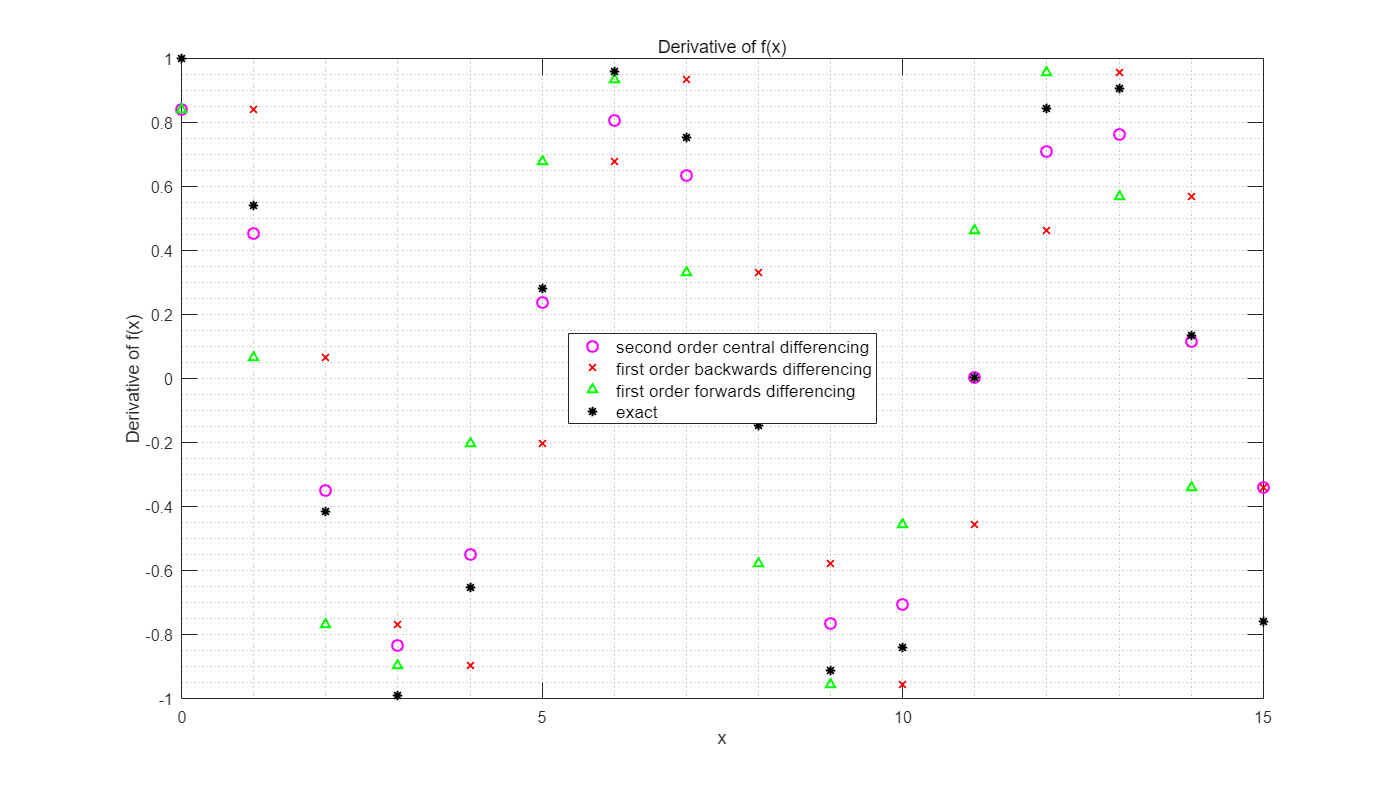

% Repeat parts 1-3 with grid spacing h=1

% Housekeeping
clear
clc

% Define the interval
hb = 1;

% Create grids of uniformly spaced points
Xb = 0 : hb : 15;

% Determine the derivative of f(x)
syms x;       % create a symbolic expression
f = sin(x);   % define the function
fd = diff(f); % differentiates f

fdb = double(subs(fd, x, Xb));

% Use first order forwards differencing to approximate the derivative of the function
fd2 = zeros(1, length(Xb) - 1); % create empty matrix to store data
fx2 = sin(Xb);                  % define the value of f(x) at each gird point

for i = 1 : length (Xb) - 1
    fd2(i) = (fx2(i + 1) - fx2(i)) / hb; % approximate the derivative of the function
end

% Use first order backwards differencing to approximate the derivative of the function
fd3 = zeros(1, length(Xb) - 1); % create empty matrix to store data
fx3 = sin(Xb);                  % define the value of f(x) at each gird point

for i = 2 : length (Xb)
    fd3(i - 1) = (fx3(i) - fx3(i - 1)) / hb; % approximate the derivative of the function
end

% Use second order central differencing to approximate the derivative of the function
fd4 = zeros(1, length(Xb)); % create empty matrix to store data
fx4 = sin(Xb);              % define the value of f(x) at each gird point

fd4(1) = fd2(1); % use first order forwards differencing at the gridpoint x1

for i = 2 : length (Xb) - 1
    fd4(i) = (fx4(i + 1) - fx4(i - 1)) / (2 * hb); % use second order central differencing at the gridpoints x2, . . . , xN−1
end

fd4(length(Xb)) = fd3(length(Xb) - 1); % use first order backwards differencing at the gridpoint xN

% Plot the approximated derivative of the function and compare with the previous three
plot(Xb(1 : length(Xb)), fd4, 'om', LineWidth = 1.5, MarkerSize = 8);     % plot second order central differencing
hold on
plot(Xb(2 : length(Xb)), fd3, 'xr', LineWidth = 1.5, MarkerSize = 7);     % plot first order backwards differencing
hold on
plot(Xb(1 : length(Xb) - 1), fd2, '^g', LineWidth = 1.5, MarkerSize = 6); % plot first order forwards differencing
hold on
plot(Xb, fdb, '*k', LineWidth = 1.5, MarkerSize = 7);                     % plot exact derivative of f(x)
hold off

title('Derivative of f(x)', FontSize = 15);
legend('second order central differencing', 'first order backwards differencing', ...
    'first order forwards differencing', 'exact', 'Location', 'Best', FontSize = 13)

xlabel('x'); 
ylabel('Derivative of f(x)');
set(gca, 'FontSize', 12)                                                  % set the fontsize of the axis

grid minor;                                                               % set the grid of the graph

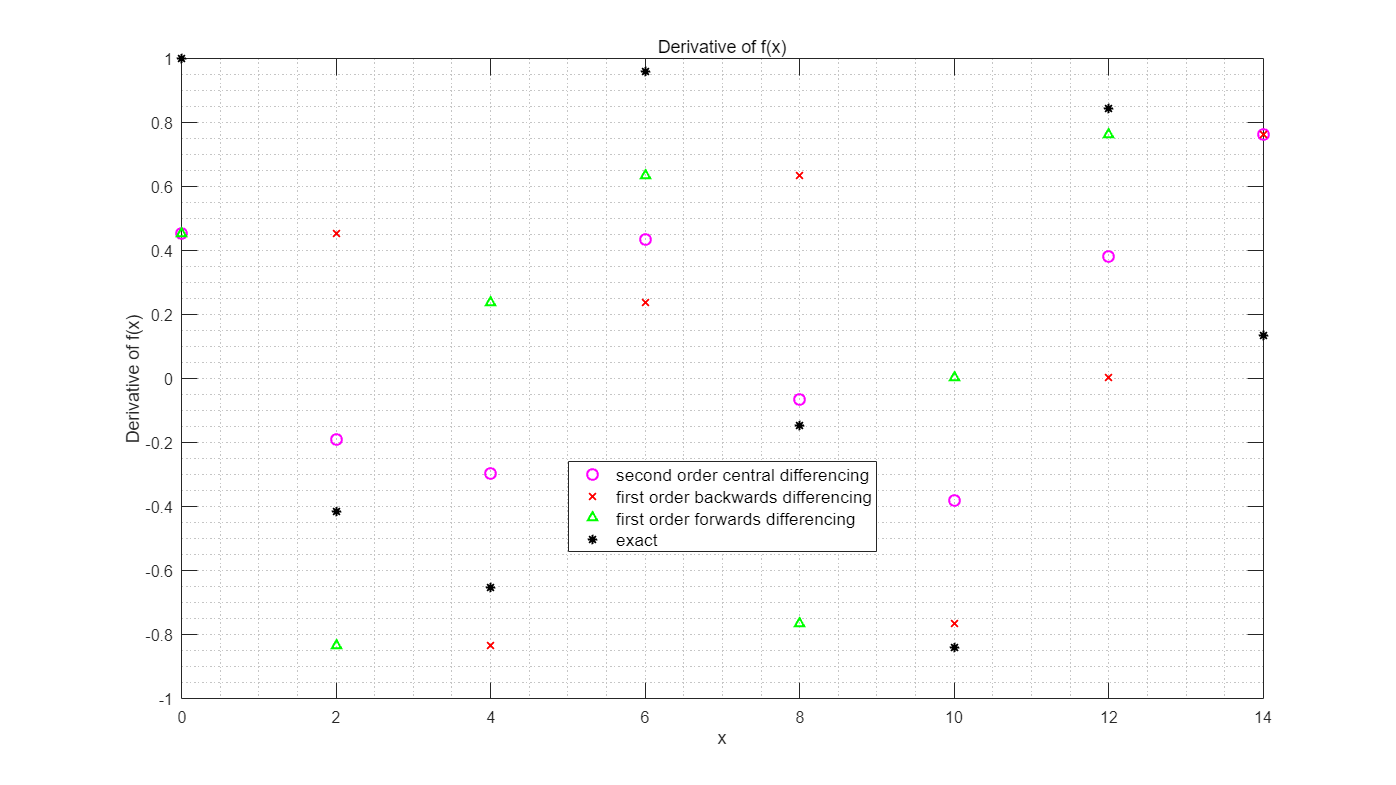

% Repeat parts 1-3 with grid spacing h=2

% Housekeeping
clear
clc

% Define the interval
hb = 2;

% Create grids of uniformly spaced points
Xb = 0 : hb : 15;

% Determine the derivative of f(x)
syms x;       % create a symbolic expression
f = sin(x);   % define the function
fd = diff(f); % differentiates f

fdb = double(subs(fd, x, Xb));

% Use first order forwards differencing to approximate the derivative of the function
fd2 = zeros(1, length(Xb) - 1); % create empty matrix to store data
fx2 = sin(Xb);                  % define the value of f(x) at each gird point

for i = 1 : length (Xb) - 1
    fd2(i) = (fx2(i + 1) - fx2(i)) / hb; % approximate the derivative of the function
end

% Use first order backwards differencing to approximate the derivative of the function
fd3 = zeros(1, length(Xb) - 1); % create empty matrix to store data
fx3 = sin(Xb);                  % define the value of f(x) at each gird point

for i = 2 : length (Xb)
    fd3(i - 1) = (fx3(i) - fx3(i - 1)) / hb; % approximate the derivative of the function
end

% Use second order central differencing to approximate the derivative of the function
fd4 = zeros(1, length(Xb)); % create empty matrix to store data
fx4 = sin(Xb);              % define the value of f(x) at each gird point

fd4(1) = fd2(1); % use first order forwards differencing at the gridpoint x1

for i = 2 : length (Xb) - 1
    fd4(i) = (fx4(i + 1) - fx4(i - 1)) / (2 * hb); % use second order central differencing at the gridpoints x2, . . . , xN−1
end

fd4(length(Xb)) = fd3(length(Xb) - 1); % use first order backwards differencing at the gridpoint xN

% Plot the approximated derivative of the function and compare with the previous three
plot(Xb(1 : length(Xb)), fd4, 'om', LineWidth = 1.5, MarkerSize = 8);     % plot second order central differencing
hold on
plot(Xb(2 : length(Xb)), fd3, 'xr', LineWidth = 1.5, MarkerSize = 7);     % plot first order backwards differencing
hold on
plot(Xb(1 : length(Xb) - 1), fd2, '^g', LineWidth = 1.5, MarkerSize = 6); % plot first order forwards differencing
hold on
plot(Xb, fdb, '*k', LineWidth = 1.5, MarkerSize = 7);                     % plot exact derivative of f(x)
hold off

title('Derivative of f(x)', FontSize = 15);
legend('second order central differencing', 'first order backwards differencing', ...
    'first order forwards differencing', 'exact', 'Location', 'Best', FontSize = 13)

xlabel('x'); 
ylabel('Derivative of f(x)');
set(gca, 'FontSize', 12)                                                  % set the fontsize of the axis

grid minor;                                                               % set the grid of the graph

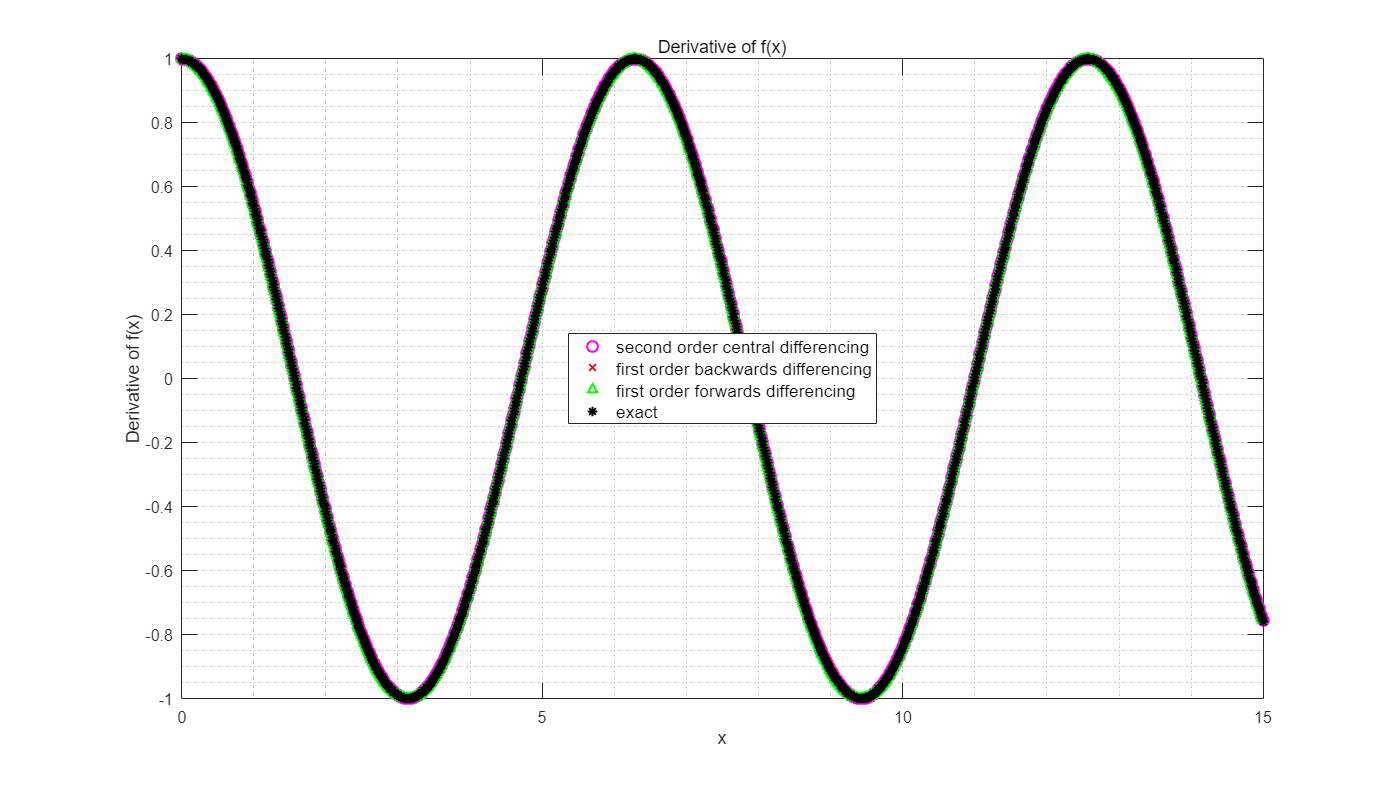


% Repeat parts 1-3 with grid spacing h=0.01

% Housekeeping
clear
clc

% Define the interval
hb = 0.01;

% Create grids of uniformly spaced points
Xb = 0 : hb : 15;

% Determine the derivative of f(x)
syms x;       % create a symbolic expression
f = sin(x);   % define the function
fd = diff(f); % differentiates f

fdb = double(subs(fd, x, Xb));

% Use first order forwards differencing to approximate the derivative of the function
fd2 = zeros(1, length(Xb) - 1); % create empty matrix to store data
fx2 = sin(Xb);                  % define the value of f(x) at each gird point

for i = 1 : length (Xb) - 1
    fd2(i) = (fx2(i + 1) - fx2(i)) / hb; % approximate the derivative of the function
end

% Use first order backwards differencing to approximate the derivative of the function
fd3 = zeros(1, length(Xb) - 1); % create empty matrix to store data
fx3 = sin(Xb);                  % define the value of f(x) at each gird point

for i = 2 : length (Xb)
    fd3(i - 1) = (fx3(i) - fx3(i - 1)) / hb; % approximate the derivative of the function
end

% Use second order central differencing to approximate the derivative of the function
fd4 = zeros(1, length(Xb)); % create empty matrix to store data
fx4 = sin(Xb);              % define the value of f(x) at each gird point

fd4(1) = fd2(1); % use first order forwards differencing at the gridpoint x1

for i = 2 : length (Xb) - 1
    fd4(i) = (fx4(i + 1) - fx4(i - 1)) / (2 * hb); % use second order central differencing at the gridpoints x2, . . . , xN−1
end

fd4(length(Xb)) = fd3(length(Xb) - 1); % use first order backwards differencing at the gridpoint xN

% Plot the approximated derivative of the function and compare with the previous three
plot(Xb(1 : length(Xb)), fd4, 'om', LineWidth = 1.5, MarkerSize = 8);     % plot second order central differencing
hold on
plot(Xb(2 : length(Xb)), fd3, 'xr', LineWidth = 1.5, MarkerSize = 7);     % plot first order backwards differencing
hold on
plot(Xb(1 : length(Xb) - 1), fd2, '^g', LineWidth = 1.5, MarkerSize = 6); % plot first order forwards differencing
hold on
plot(Xb, fdb, '*k', LineWidth = 1.5, MarkerSize = 7);                     % plot exact derivative of f(x)
hold off

title('Derivative of f(x)', FontSize = 15);
legend('second order central differencing', 'first order backwards differencing', ...
    'first order forwards differencing', 'exact', 'Location', 'Best', FontSize = 13)

xlabel('x'); 
ylabel('Derivative of f(x)');
set(gca, 'FontSize', 12)                                                  % set the fontsize of the axis

grid minor;                                                               % set the grid of the graph

#### Exercise 2 (The second derivative of a sinusoidal function)

Consider the function 

f(x) = sin(x), 

and the interval x ∈ [0, 15]. We wish to compute the second derivative of f(x) numerically. Again, we create a grid of uniformly spaced points (with some uniform spacing h > 0) from x = 0 to x = 15. We can again label each point on the grid as x1, x2, . . . , xN (again, starting with index 1 is an arbitrary choice). 

1. Determine the second derivative of f(x) with respect to x analytically. 

(a) Plot the second derivative of the function for x in the interval of interest. 

(b) Pick h = 0.5 (we will vary the grid sizing later) and plot (on the same figure), using asterisks, the (exact) second derivative of f(x) at each grid point. 

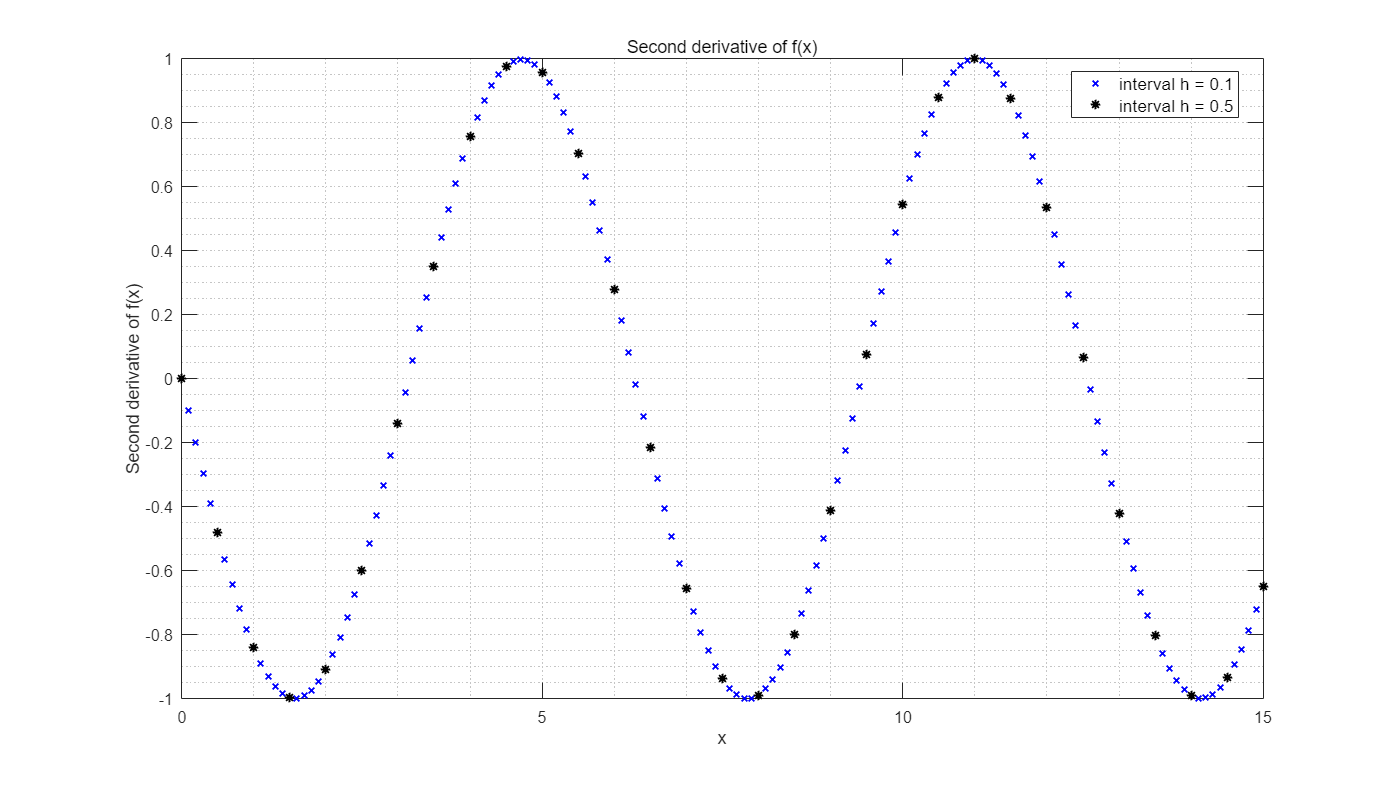

% Housekeeping
clear
clc
close all

% Define the interval
ha = 0.1;
hb = 0.5;

% Create grids of uniformly spaced points
Xa = 0 : ha : 15;
Xb = 0 : hb : 15;

% Determine the derivative of f(x)
syms x;       % create a symbolic expression
f = sin(x);   % define the function
fdd = diff(diff(f)); % differentiates f twice

fdda = double(subs(fdd, x, Xa)); % for ha
fddb = double(subs(fdd, x, Xb)); % for hb

% Plot the second derivative of the function
plot(Xa, fdda, 'xb', LineWidth = 1.5, MarkerSize = 6); % plot second derivative of f(x) in the interval of interest for ha
hold on
plot(Xb, fddb, '*k', LineWidth = 1.5, MarkerSize = 7); % plot second derivative of f(x) in the interval of interest for hb
hold off

title('Second derivative of f(x)', FontSize = 15);
legend(['interval h = ', num2str(ha)], [ 'interval h = ', num2str(hb) ], 'Location', 'Best', FontSize = 13)

xlabel('x'); 
ylabel('Second derivative of f(x)');
set(gca, 'FontSize', 12)                            % set the fontsize of the axis

grid minor;                                         % set the grid of the graph
set(gcf, 'Position', [0 0 1920 1080]);              % show plot with larger size

2. We now wish to compute the second derivative of the function using second order central differencing with h = 0.5. 

(a) Use second order central differencing to approximate the second derivative of the function at the grid points x2, x3, . . . , xN−1. 

(b) Plot the numerical approximation of the derivative computed in part (a). 

(c) Plot (on the same figure), using asterisks, the (exact) second derivative of f(x) at each grid point. 

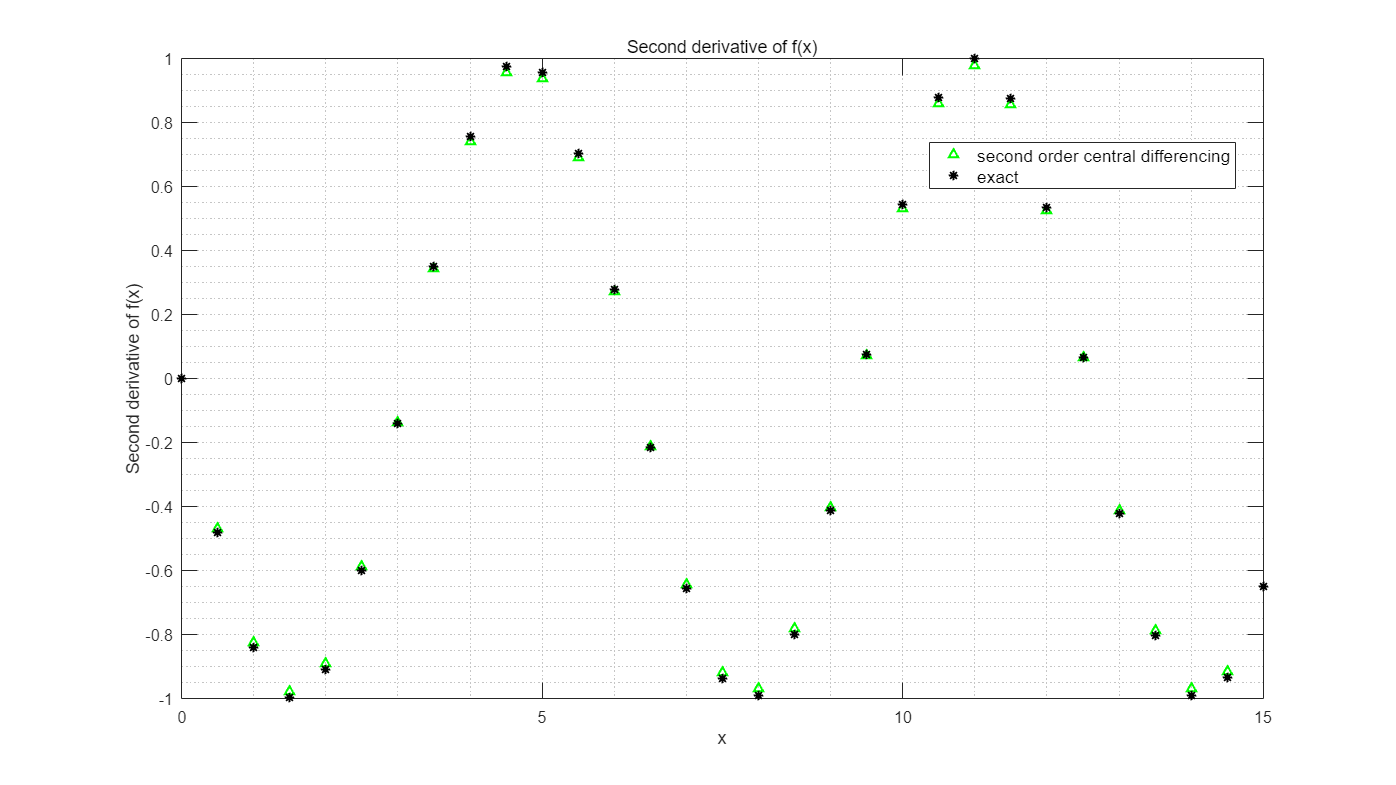

% Use second order central differencing to approximate the second derivative of the function
fdd2 = zeros(1, length(Xb) - 2); % create empty matrix to store data
fx2 = sin(Xb);                   % define the value of f(x) at each gird point

for i = 2 : length (Xb) - 1
    fdd2(i - 1) = (fx2(i + 1) + fx2(i - 1)- 2 * fx2(i)) / hb ^ 2; % approximate the second derivative of the function
end

% Plot the approximated derivative of the function and compare with the exact one
plot(Xb(2 : length(Xb) - 1), fdd2, '^g', LineWidth = 1.5, MarkerSize = 6); % plot second order central differencing
hold on
plot(Xb, fddb, '*k', LineWidth = 1.5, MarkerSize = 7);                     % plot exact second derivative of f(x)
hold off

title('Second derivative of f(x)', FontSize = 15);
legend('second order central differencing', 'exact', 'Location', 'Best', FontSize = 13)

xlabel('x'); 
ylabel('Second derivative of f(x)');
set(gca, 'FontSize', 12)                                                  % set the fontsize of the axis

grid minor;                                                               % set the grid of the graph

3. 

(a) Repeat parts 1-2 with different grid spacing h and compare the “numerical approximations” with the derivative calculated analytically for the different values of h. What do you observe? 

(b) In a new figure, plot the error at each of the gridpoint x2, . . . , xN−1 for three different stepsizes h (e.g. h = 0.1, h = 0.5 and h = 1).

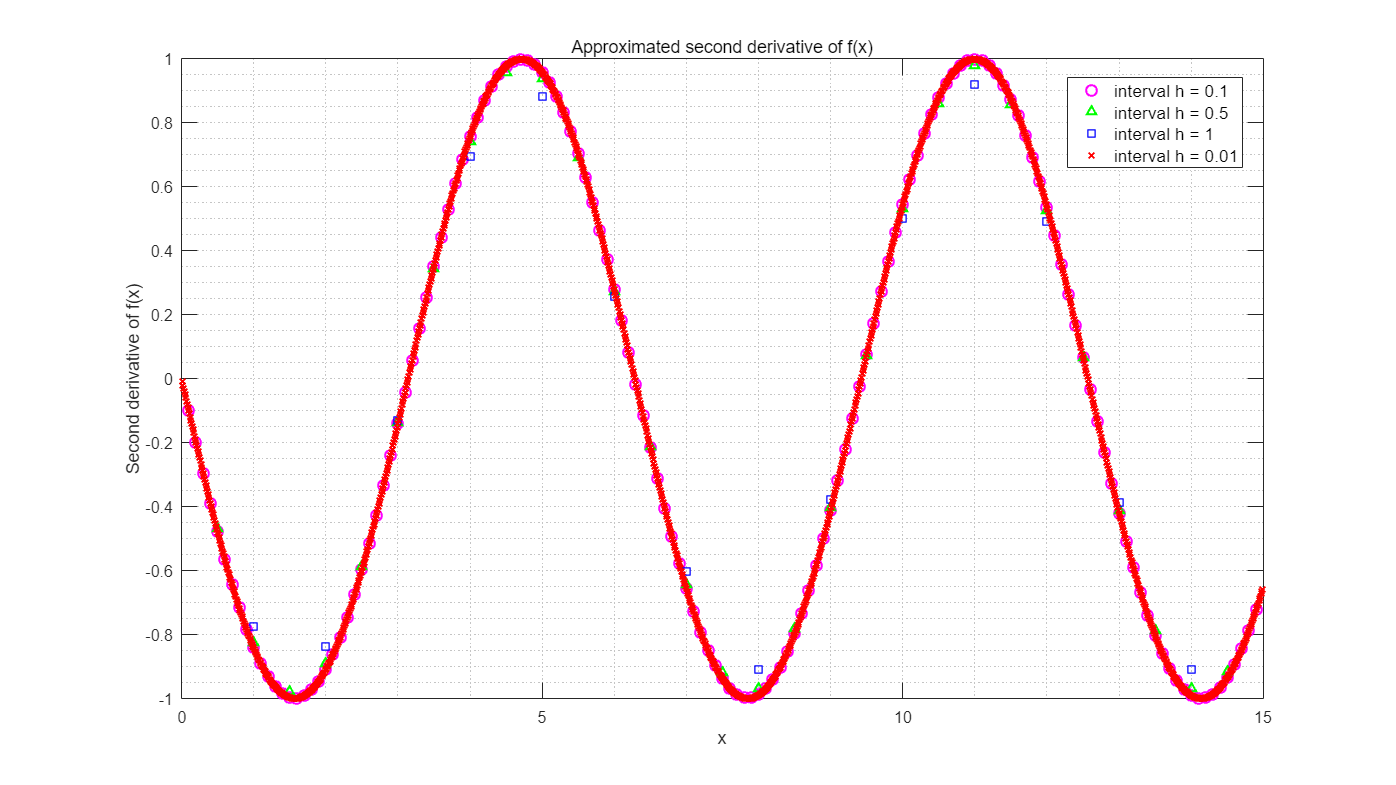

% Define interval
hc = 1;
hd = 0.01;

% Create grids of uniformly spaced points
Xc = 0 : hc : 15;
Xd = 0 : hd : 15;

% Determine the derivative of f(x)
syms x;       % create a symbolic expression
f = sin(x);   % define the function
fdd = diff(diff(f)); % differentiates f twice

fddc = double(subs(fdd, x, Xc)); % for hc
fddd = double(subs(fdd, x, Xd)); % for hd

% Use second order central differencing to approximate the second derivative of the function for ha
fdd2a = zeros(1, length(Xa) - 2); % create empty matrix to store data
fx2a = sin(Xa);                   % define the value of f(x) at each gird point

for i = 2 : length (Xa) - 1
    fdd2a(i - 1) = (fx2a(i + 1) + fx2a(i - 1)- 2 * fx2a(i)) / ha ^ 2; % approximate the second derivative of the function
end

% Use second order central differencing to approximate the second derivative of the function for hc
fdd2c = zeros(1, length(Xc) - 2); % create empty matrix to store data
fx2c = sin(Xc);                   % define the value of f(x) at each gird point

for i = 2 : length (Xc) - 1
    fdd2c(i - 1) = (fx2c(i + 1) + fx2c(i - 1)- 2 * fx2c(i)) / hc ^ 2; % approximate the second derivative of the function
end

% Use second order central differencing to approximate the second derivative of the function for hd
fdd2d = zeros(1, length(Xd) - 2); % create empty matrix to store data
fx2d = sin(Xd);                   % define the value of f(x) at each gird point

for i = 2 : length (Xd) - 1
    fdd2d(i - 1) = (fx2d(i + 1) + fx2d(i - 1)- 2 * fx2d(i)) / hd ^ 2; % approximate the second derivative of the function
end

% Plot the approximated second derivative of the function with different interval
plot(Xa(2 : length(Xa) - 1), fdd2a, 'om', LineWidth = 1.5, MarkerSize = 8); % for ha
hold on
plot(Xb(2 : length(Xb) - 1), fdd2, '^g', LineWidth = 1.5, MarkerSize = 6);  % for hb
hold on
plot(Xc(2 : length(Xc) - 1), fdd2c, 'sb', LineWidth = 1.5, MarkerSize = 7); % for hc
hold on
plot(Xd(2 : length(Xd) - 1), fdd2d, 'xr', LineWidth = 1.5, MarkerSize = 6); % for hd
hold off

title('Approximated second derivative of f(x)', FontSize = 15);
legend(['interval h = ', num2str(ha)], [ 'interval h = ', num2str(hb) ], [ 'interval h = ', num2str(hc) ], ...
    [ 'interval h = ', num2str(hd) ], 'Location', 'Best', FontSize = 13)

xlabel('x'); 
ylabel('Second derivative of f(x)');
set(gca, 'FontSize', 12)                            % set the fontsize of the axis

grid minor;                                         % set the grid of the graph

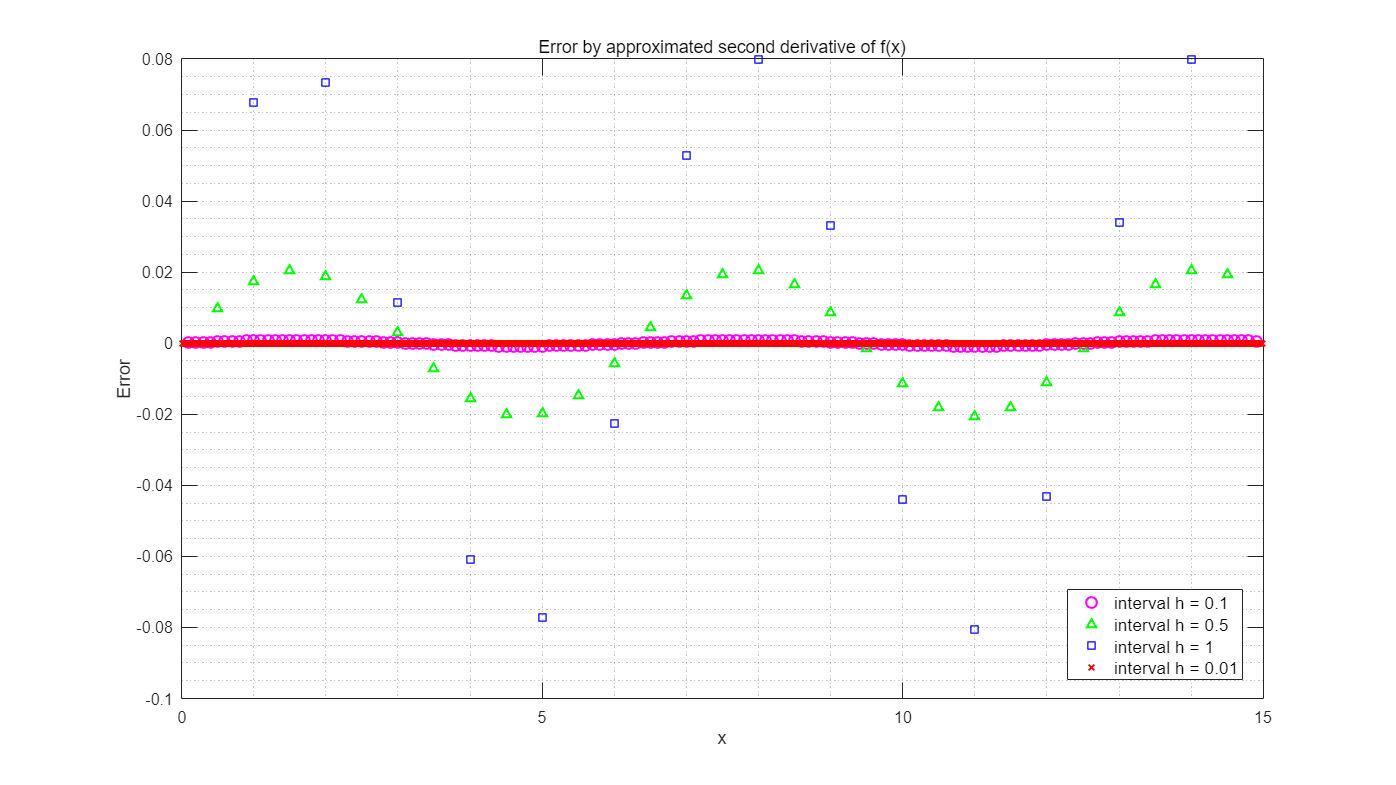

% Find error at each of the grid points
ea = fdd2a - fdda(2 : length(fdda) - 1); % for ha
eb = fdd2 - fddb(2 : length(fddb) - 1);  % for hb
ec = fdd2c - fddc(2 : length(fddc) - 1); % for hc
ed = fdd2d - fddd(2 : length(fddd) - 1); % for hd

% Plot the error at each of the gridpoint for different stepsizes
plot(Xa(2 : length(Xa) - 1), ea, 'om', LineWidth = 1.5, MarkerSize = 8); % for ha
hold on
plot(Xb(2 : length(Xb) - 1), eb, '^g', LineWidth = 1.5, MarkerSize = 6);  % for hb
hold on
plot(Xc(2 : length(Xc) - 1), ec, 'sb', LineWidth = 1.5, MarkerSize = 7); % for hc
hold on
plot(Xd(2 : length(Xd) - 1), ed, 'xr', LineWidth = 1.5, MarkerSize = 6); % for hd
hold off

title('Error by approximated second derivative of f(x)', FontSize = 15);
legend(['interval h = ', num2str(ha)], [ 'interval h = ', num2str(hb) ], [ 'interval h = ', num2str(hc) ], ...
    [ 'interval h = ', num2str(hd) ], 'Location', 'Best', FontSize = 13)

xlabel('x'); 
ylabel('Error');
set(gca, 'FontSize', 12)                            % set the fontsize of the axis

grid minor;                                         % set the grid of the graph